# Επιστημονικός Υπολογισμός Εργαστηριακή Ασκηση

# **0 Στοιχεία υπολογιστικού συστήματος**

**1) **31/01/2025 - 09/01/2025

**2)i)**

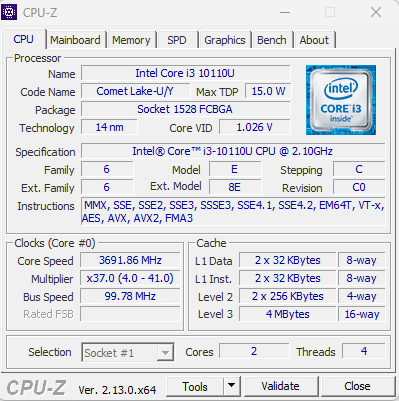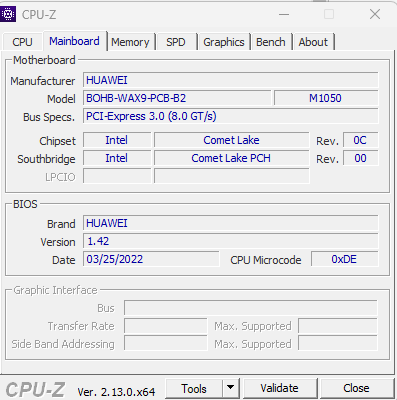

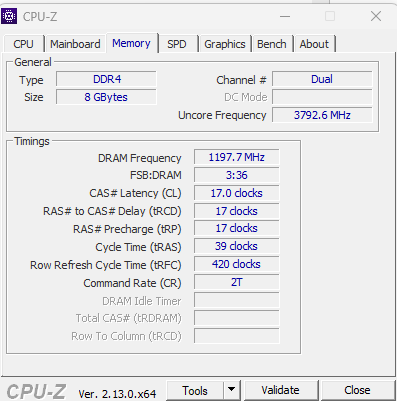

**ii)**

disp("=== MATLAB Information ===")

=== MATLAB Information ===


disp(['MATLAB Version: ', version])

MATLAB Version: 23.2.0.2428915 (R2023b) Update 4


disp(['MATLAB Release: ', version('-release')])

MATLAB Release: 2023b


**iii)**

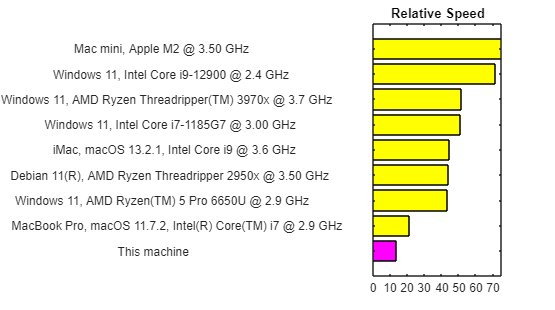

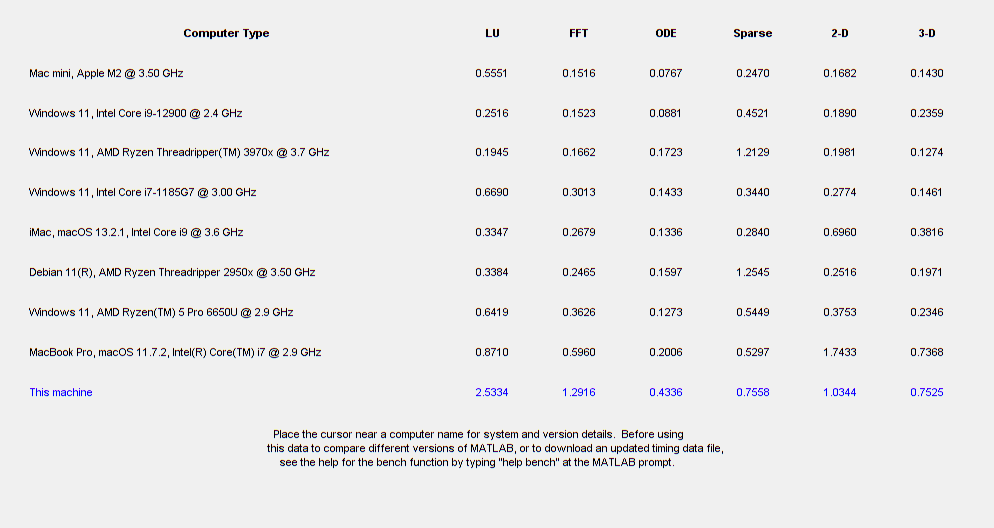

ans =     2.5334    1.2916    0.4336    0.7558    1.0344    0.7525


bench

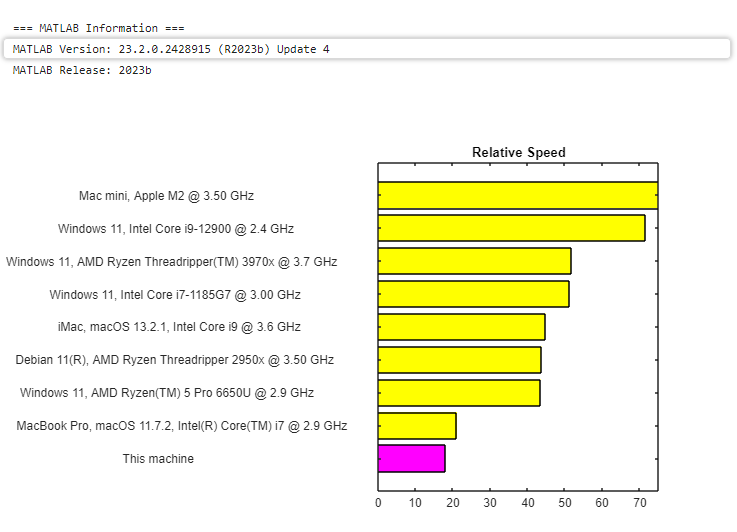

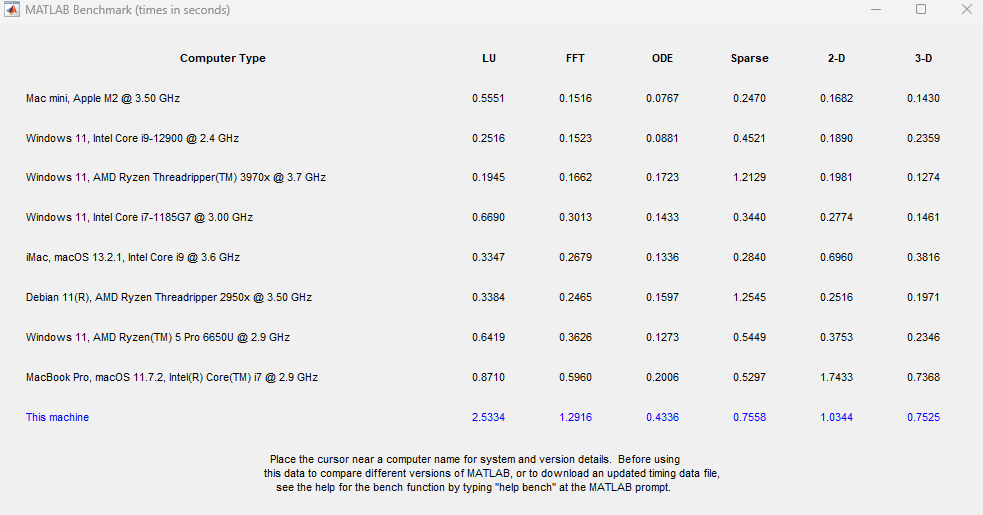

# 1 Ειδικοί επιλυτές και αραιά μητρώα

Αρχικά θα πρέπει να εισάγουμε ένα τριδιαγώνιο μητρώο

Α = $\left\lbrack \begin{array}{cccccccc}
a_{11}  & a_{12}  & a_{13}  & 0 & \ldotp \ldotp  &  & \ldotp \ldotp  & 0\\
a_{21}  & a_{22}  & a_{23}  & \ldotp \ldotp  & 0 & \ldotp \ldotp  & \ldotp \ldotp  & 0\\
0 & a_{32}  & a_{33}  & a_{34}  & 0 & 0 & \ldotp \ldotp  & \\
0 & 0 & a_{43}  & a_{44}  & a_{45}  & 0 & \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  &  &  &  & \ldotp \ldotp  & a_{n-1n} \\
0 & 0 & \ldotp \ldotp  & \ldotp \ldotp  &  &  & a_{\textrm{nn}-1}  & a_{\textrm{nn}} 
\end{array}\right\rbrack$

και στην συνέχεια μέσω της διαδιακασιας που περιγράφεται στο  set11 σελίδα 14 - Επίλυση με αναγωγές θα διασπάσουμε τον Α σε Α = D - L - U. H επίλυση του συστήματος  Ax = b είναι ισοδύναμη με την επίλυση του


$$(D^{(1)} - L^{(1)} - U^{(1)})x = b^{(1)}$$


όπου


$$D^{(1)} = D -LD^{-1}U - UD^{-1}L$$



$$L^{(1)} = LD^{-1}L$$



$$U^{\left(1\right)} ={\textrm{UD}}^{-1} U$$



$$b^{\left(1\right)} =b\;+{\textrm{LD}}^{-1} b\;+{\textrm{UD}}^{-1} b$$


Το σύστημα θα έρθει σε μορφή που θα εχει μη μηδενικά μόνον στις θέσεις της διαγωνίου, της 2ης υποδιαγωνίου και της 2ης υπερδιαγωνίου. Στην συνέχεια χρησιμοποιώντας πράξεις Hadamard (συγκεκριμένα διαίρεση στοιχείο προς στοιχείο) λύνουμε το σύστημα. Συνεχίζοντας επαναληπτικά την διαδικασια το σύστημα θα γίνει διαγώνιο

## Ερώτημα 2

n_values = [2^4, 2^8]; 

for n = n_values
    A = toeplitz([4, -1, zeros(1, n-2)]); 

    
    B1 = A * ones(n, 1);            
    B10 = A * tril(ones(n, 10));    

    %Λύση με τον Αλγόριθμο
    X1 = tridReduct_my4236182(A, B1);
    X10 = tridReduct_my4236182(A, B10);

    % Λύση με την mldivide
    X1_matlab = A \ B1;
    X10_matlab = A \ B10;

    % Νορμα Μεγίστου για την διαφορά
    diff1 = norm(X1 - X1_matlab, inf);
    diff10 = norm(X10 - X10_matlab, inf);

    % Αποτελέσματα
    fprintf('--- Αποτελέσματα για n = %d ---\n', n);
    fprintf('Μέγιστη διαφορά για 1 δεξιό μέλος: %.5e\n', diff1);
    fprintf('Μέγιστη διαφορά για 10 δεξιά μέλη: %.5e\n', diff10);

    % Έλεγχος αποτελεσμάτων
    condA = cond(A); % Δείκτης κατάστασης 
    tolerance = condA * eps;
    if diff1 > tolerance
        fprintf('Μεγάλο σφάλμα\n');
    else
        fprintf('Σωστό Αποτέλεσμα.\n');
    end
    if diff10 > tolerance
        fprintf('Μεγάλο σφάλμα\n');
    else
        fprintf('Σωστό Αποτέλεσμα.\n');
    end
end

--- Αποτελέσματα για n = 16 ---


Μέγιστη διαφορά για 1 δεξιό μέλος: 1.11022e-16


Μέγιστη διαφορά για 10 δεξιά μέλη: 9.00000e+00


Σωστό Αποτέλεσμα.


Μεγάλο σφάλμα


--- Αποτελέσματα για n = 256 ---


Μέγιστη διαφορά για 1 δεξιό μέλος: 2.22045e-16


Μέγιστη διαφορά για 10 δεξιά μέλη: 9.00000e+00


Σωστό Αποτέλεσμα.


Μεγάλο σφάλμα


Σχολιασμός αποτελεσμάτων: Για το συγκριμένο σύστημα έγινε μια επανάληψη της διαδικασίας. Παρατηρούμε ότι μας δίνει σωστό σφάλμα για την πρώτη περίπτωση για n = 16 και για n = 256. Αντίθετα στην δεύτερη περίπτωση με τα 10 δεξιά μέλη θα έπρεπε να κάνουμε τουλάχιστον ακόμη μια επανάληψη και να προσδιορίσουμε τους $A^{\left(2\right)}$ και $b^{\left(2\right)}$. Για να μειωθεί το κόστος πράξεων θα μπορούσαμε να κάνουμε και πράξεις Hadamard για τη  κατασκευή των πινάκων. 

## **Ερώτημα 3 **

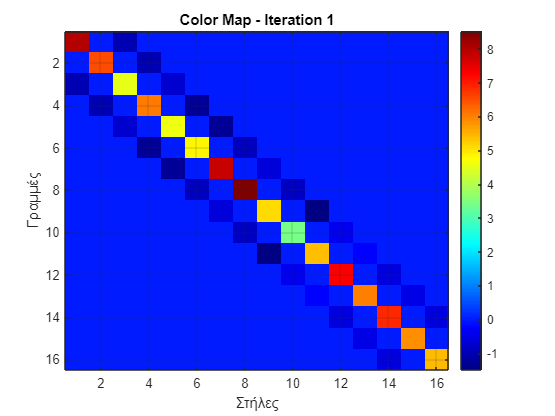

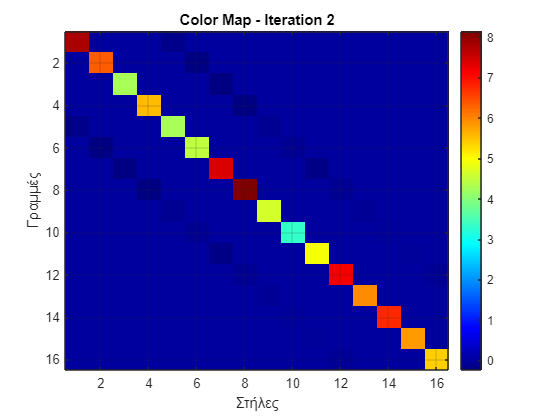

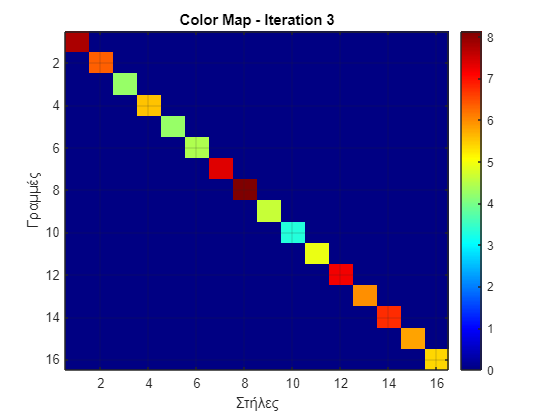

%Αρχικοποίηση
n = 16; % Διάσταση του πίνακα
n_iterations = 3; % Αριθμός επαναλήψεων

% --- Δημιουργία Συμμετρικού Θετικά Ορισμένου Τριδιαγώνιου Πίνακα ---
main_diag = randi([6, 10], n, 1);      % Κύρια διαγώνιος (μεγάλες τιμές για θετική οριστικότητα)
sub_diag = randi([-3, -1], n-1, 1);    % Υποδιαγώνιος
super_diag = sub_diag;                 % Υπερδιαγώνιος (ίδια τιμή για συμμετρία)
A_0 = diag(main_diag) + diag(sub_diag, -1) + diag(super_diag, 1);

%Αποθήκευση νόρμων στις επαναλήψεις ---
norm_main = zeros(n_iterations, 1);  % Κύρια διαγώνιος
norm_super = zeros(n_iterations, 1); % Υπερδιαγώνιος
norm_sub = zeros(n_iterations, 1);   % Υποδιαγώνιος

% Έναρξη επαναληπτικής διαδικασίας
A_k = A_0; % Ορίζουμε A_0

for k = 1:n_iterations
    % Διάσπαση A_k σε D_k, L_k, U_k
    D_k = diag(diag(A_k)); % Διαγώνιος πίνακας
    L_k = -tril(A_k, -1);  % Κάτω τριγωνικός χωρίς την κύρια διαγώνιο
    U_k = -triu(A_k, 1);   % Άνω τριγωνικός χωρίς την κύρια διαγώνιο

    %Υπολογισμός νέου πίνακα A_{k+1} σύμφωνα με τον αλγόριθμο
    A_k = (D_k + L_k + U_k) * (D_k \ A_k); % Χρήση του D_k \ A_k αντί για inv(D_k) * A_k

    % Υπολογισμός νόρμας μεγίστου για κάθε διαγώνιο
    norm_main(k) = norm(diag(A_k), inf);         % Κύρια διαγώνιος
    norm_super(k) = norm(diag(A_k, 1), inf);     % Υπερδιαγώνιος
    norm_sub(k) = norm(diag(A_k, -1), inf);      % Υποδιαγώνιος

    %Σχεδίαση του πίνακα 
    figure;
    imagesc(A_k); 
    colorbar; 
    colormap jet; 
    title(['Color Map - Iteration ', num2str(k)]);
    xlabel('Στήλες');
    ylabel('Γραμμές');
    grid on;
    pause(0.5);
end

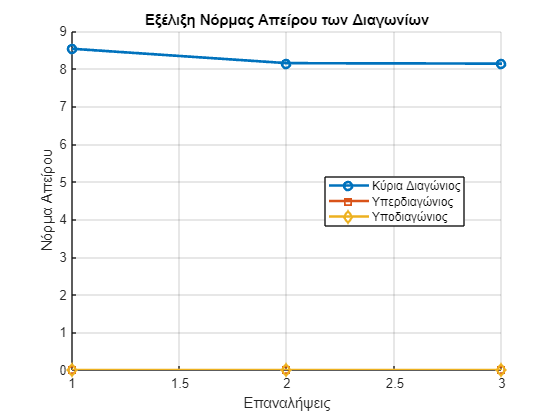


% --- Γράφημα των Νορμών ---
figure;
hold on;
plot(1:n_iterations, norm_main, '-o', 'LineWidth', 2, 'DisplayName', 'Κύρια Διαγώνιος');
plot(1:n_iterations, norm_super, '-s', 'LineWidth', 2, 'DisplayName', 'Υπερδιαγώνιος');
plot(1:n_iterations, norm_sub, '-d', 'LineWidth', 2, 'DisplayName', 'Υποδιαγώνιος');
hold off;

xlabel('Επαναλήψεις');
ylabel('Νόρμα Απείρου');
title('Εξέλιξη Νόρμας Απείρου των Διαγωνίων');
legend('show', 'Location', 'best');
grid on;

## ** Σχολιασμός Αποτελεσμάτων **

Αφου κατασκευάστηκε η επαναληπτική διαδικασια για την επίλυση με αναγωγές, εφαρμόστηκε σε τυχαίους σ.θ.ο. πίνακες. Η μορφή του πίνακα $A^{\left(n\right)}$ αναπαριστάται με colormar και συμφωνεί με γραφήματα του set 11 σελίδα 19. O πίνακας αναγάγεται σε διαγώνιο. Πράγμα που επιβεβαιώνεται και από τις νόρμες μεγίστου στις άλλες διαγωνίους οι οποίες τείνουν στο μηδέν. Αρα υπάρχει σύγκλιση. 

function x = tridReduct_my4236182(A, b)
    % Ελέγχει αν ο A είναι τετραγωνικός πίνακας
    [m, n] = size(A);
    if m ~= n
        error('Ο πίνακας A πρέπει να είναι τετραγωνικός');
    end

    % Υπολογισμός των D, L, U
    D = diag(diag(A)); % Διαγώνιος πίνακας
    L = -tril(A, -1);  % Κάτω τριγωνικός χωρίς την κύρια διαγώνιο
    U = -triu(A, 1);   % Άνω τριγωνικός χωρίς την κύρια διαγώνιο

    % Υπολογισμός D1, L1, U1
    D1 = D - L * (D \ U) - U * (D \ L); 
    L1 = L * (D \ L);                   
    U1 = U * (D \ U);                   

    % Υπολογισμός του b^(1)
    b1 = b + L * (D \ b) + U * (D \ b);

    % Υπολογισμός των διαγωνίων του D1 - L1 - U1
    A1 = D1 - L1 - U1;
    d_main = diag(A1);                % Κύρια διαγώνιος
    d_super2 = [diag(A1, 2); 0; 0];   % 2η υπερδιαγώνιος
    d_sub2 = [0; 0; diag(A1, -2)];    % 2η υποδιαγώνιος

    % Επίλυση με Hadamard πράξεις
    n = length(b);
    x = zeros(n, 1);

    % Πίσω αντικατάσταση
    for i = 3:n
        factor = d_sub2(i) ./ d_main(i-2); % Παράγοντες εξάλειψης
        d_main(i) = d_main(i) - factor .* d_super2(i-2);
        b1(i) = b1(i) - factor .* b1(i-2);
    end

    % Μπροστά αντικατάσταση 
    x(n) = b1(n) ./ d_main(n); % Τελευταίο στοιχείο
    x(n-1) = (b1(n-1) - d_super2(n-1) .* x(n)) ./ d_main(n-1); % Προτελευταίο στοιχείο

    for i = n-2:-1:1
        x(i) = (b1(i) - d_super2(i) .* x(i+2)) ./ d_main(i); % Υπόλοιπα στοιχεία
    end
end

